Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" ([https://www.crcpress.com/9781138589940](https://www.crcpress.com/9781138589940))

# C-magnet (Section 4.3.2)

Volker Ziemann, 211107, CC-BY-SA-4.0

**Important:** this example requires the PDE toolbox!

Magnetostatic problems in two dimensions $x$ and $y$ are described by the Poisson equation for the vector potential $A_z$


$$-\vec{\nabla} \cdot \left(\frac{1}{\mu_r }\vec{\nabla} A_z \right)=\mu_0 J_z$$
 

where $J_z$ is the density [A/${\textrm{mm}}^2$] of a current flowing in the $z$ direction. In the following example we will analyze a C-shaped dipole magnet and then use the Poisson equation to find $A_z$ from which we derive the magnetic field components $B_x$ and $B_y$.

The geometry of this C-shaped dipole magnet consisting of an iron `yoke`, current-carrying coils `C1` to `C4`, and some space around the magnet that we call `World`.  Each part is defined by  a column vector of the same length. The `yoke` is the longest vector and is defined as a polygon (first entry is 2), defined by 13 points (second entry), followed by the 13 x-positions and then the 13 y-positions of each of the defining points. The four coils are defined as rectangles by using 3 and 4 as first and second entry in their definitions, again, followed by the four x-positions and the four y-positions. Likewise the enclosing  volume, the World, is defined as a rectangle. Note the zeros appended to the end of `Cn` and the `World`. They are required (by MATLAB internals) to make all column vectors that define the geometry have equal length. See the definition of gd below, which is an array of these column vectors and if defined this way the entries must have equal length.

clear all; close all
yoke=[2; 13; ...    %..Yoke
    0;0;0.3;0.3;1;1;-0.6;-0.6;1;1;0.3;0.3;0; ...
    0;0.3;0.3;0.05;0.05;0.8;0.8;-0.8;-0.8;-0.05;-0.05;-0.3;-0.3];
C1=[3;4;0;0;0.3;0.3;  0.1;0.3;0.3;0.1;zeros(18,1)];
C2=[3;4;1;1;1.3;1.3;  0.1;0.3;0.3;0.1;zeros(18,1)];
dy=0.4;
C3=[3;4;0;0;0.3;0.3;  0.1-dy;0.3-dy;0.3-dy;0.1-dy;zeros(18,1)];
C4=[3;4;1;1;1.3;1.3;  0.1-dy;0.3-dy;0.3-dy;0.1-dy;zeros(18,1)];
World=[3;4;-1.8;1.8;1.8;-1.8;-1.2;-1.2;1.2;1.2;zeros(18,1)];

Now we are ready to assemble the geometry into a single structure called` gd`, name the regions with` ns`, and define the relation among the different regions in `sf`. The call to the function `decsg() `the combines this information into a single entity` g ` that describes the geometry.

gd=[World,yoke,C1,C2,C3,C4];  % assemble geometry
ns=char('World','yoke','C1','C2','C3','C4')';  % names of the regions                 
sf='World+yoke+C1+C2+C3+C4';
g=decsg(gd,sf,ns); 

The following code first creates a model with one dynamic variable, which is the z-component $A_z$ of the vector potential. Internally MATLAB calls the single dynamic variable `u`. Then MATLAB internally generates the structure `model` from the provided geometry g, which we immediately plot. First we ask MATLAB to display the` EdgeLabels`, because we need them to specify boundary conditions`.`

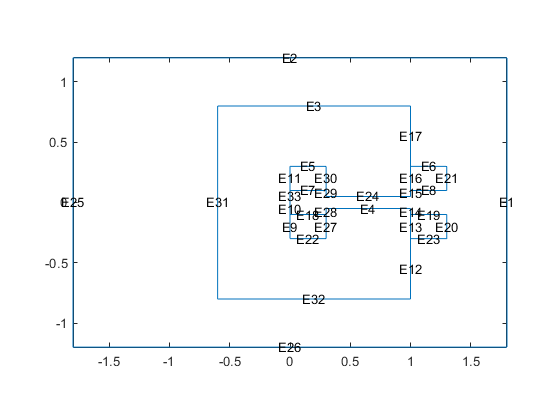

model=createpde(1); 
geometryFromEdges(model,g);
pdegplot(model,'EdgeLabels','on'); 

Now we are ready to specify the boundary conditions with `applyBoundaryCondition(). `Note that the numbers in the array  `[1,2,25,26] `correspond to the outer walls of the integration volume which is far away from the magnet and we require u = $A_z$ to  vanish. All internal boundaries are automatically taken care of by MATLAB and we need not specify them.

applyBoundaryCondition(model,'Edge',[1,2,25,26],'u',0);

 In the next plot we ask MATLAB to display the `SubDomainLabels`, which we need to specify the material coefficients in the respective regions.

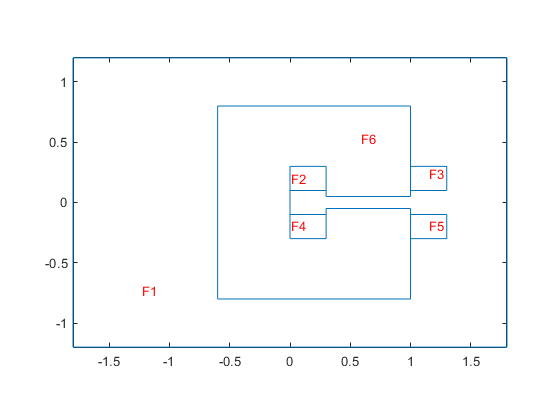

figure; 
pdegplot(model,'SubDomainLabels','on'); 

Once we know the names, we can use them to define the material in the respective regions. Here '1' referes to the region, labeled 'F1' in the plot. The material coefficients  `m, d, c, a,` and f refer to MATLAB's way of specifying the coefficients of a partial differential equation, outlined in the following equation

    
$$ m\frac{\partial^2u}{\partial t^2}+d\frac{\partial u}{\partial t}-\vec\nabla\cdot\left(c \vec\nabla u\right) + a u = f
$$


This equation has the form of the Poisson equation, shown above, provided we set $m=d=a=0$ and identify $c=1/\mu_r$ and $f=-\mu_0 J_z$. The following calls to `specifyCoefficients()` define these coefficients in all regions. Here we chosse a current density that corresponds to N I = 40 kA turns flowing through the coils. See the book for a more detailed discussion. 

specifyCoefficients(model,'m',0,'d',0,'c',1,'a',0,'f',0,'Face',1);
specifyCoefficients(model,'m',0,'d',0,'c',1,'a',0,'f',0.8378,'Face',[2,4]);
specifyCoefficients(model,'m',0,'d',0,'c',1,'a',0,'f',-0.8378,'Face',[3,5]);
specifyCoefficients(model,'m',0,'d',0,'c',1/5000,'a',0,'f',0,'Face',6);

The next step is to generate the mesh with a call to `generateMesh().` Note that  we specify the maximum mesh size by specifying the parameter `Hmax `to be 0.05 before displaying the resulting mesh with a call to the built-in function` pdemesh()`.

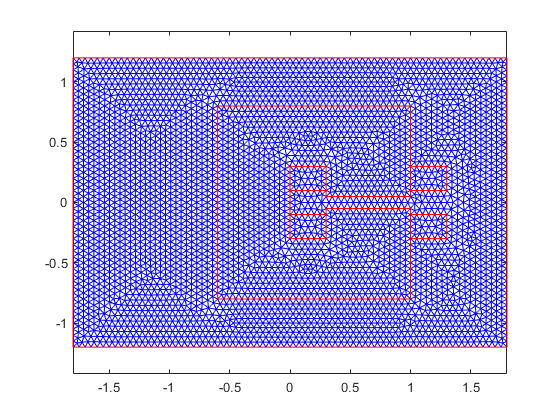

generateMesh(model,'Hmax',0.05); 
figure; pdemesh(model); 

After having defined the geometry, the boundary conditions, the material properties and the mesh, we are ready to calculate the vector potential with a call to `solvepde()`, which returns the structure `result `that contains all relevant information about the solution. Then we plot the value of u= $A_z$ (including contour lines) in the call to pdeplot(). Note that `result.NodalSolution` is MATLAB's way of specifying u.

result=solvepde(model);
figure; pdeplot(model,'XYdata',result.NodalSolution,'contour','on');

Since it is nice to see the magnet superimposed ('hold on') to the field, we just plot the model that contains the geometry definition o top of the field u.

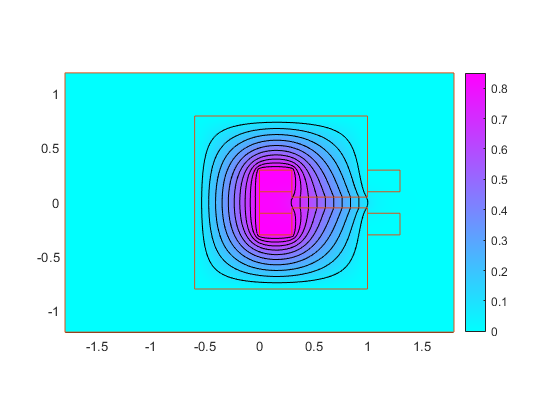

hold on; 
pdegplot(model); 

But it's not so much the vector potential $u=A_z$ we are interested in, it's the magentic field components $B_x=\partial A_z/\partial y$ and $B_x=-\partial A_z/\partial x$ or its magnitude $|B|=\sqrt{B_x^2+B_y^2}$   we want to know. The gradients are available from the structure `result `as members `XGradients` and `YGradients`.  Then we calculate $|B|$, plot its value an superimpose the geometry.

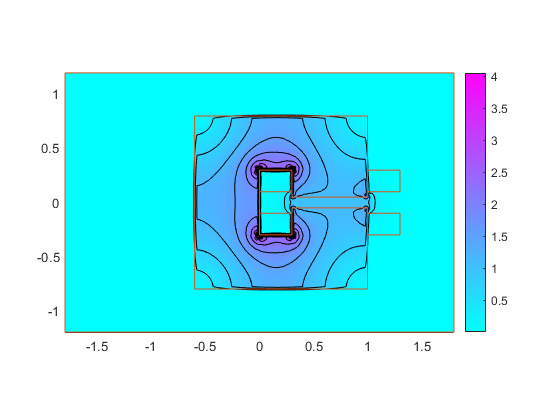

Bn=hypot(result.XGradients,result.YGradients);
figure; 
pdeplot(model,'xydata',Bn,'contour','on'); 
hold on; 

pdegplot(model);

Here we observe from the colorbar on the left  that the magnitude of $|B|$ reaches 4 T and that the maximum field occurs at the corners insie the yoke, next to the coils, where the field lines 'crowd' to get around the corner inside the iron with large $\mu_r$ rather than taking a shortcut through the coil with $\mu_r=1$. 

Finally we plot $|B|$ inside the gap of the magnet, which is where a particle beam would travel. To do  so, we define the path` x,y` along  which we want to plot the field, evaluate the gradients with evaluateGradient() along the path, specified by x and y, plot the data and annotate the plot.

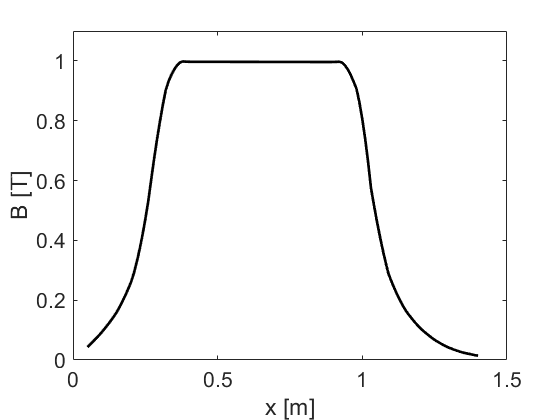

x=0.05:0.01:1.4; y=zeros(1,length(x));
[By,Bx]=evaluateGradient(result,x,y);  Bx=-Bx;
B=hypot(Bx,By);
figure; plot(x,B,'k','LineWidth',2)
xlabel('x [m]'); ylabel('B [T]'); ylim([0,1.1]); 
set(gca,'FontSize',16);

We observe that the field inside the gap reaches 1 T and appears to be reasonably constant (at this scape). As an exercise, please plot $B_y$ along the same path and explore how it changes, if the y-position of the line along which we evaluate the field is moved sloser to the gap. We note that the field rolls off at the ends of the gap, which is something we will fix by adding small pieces of iron close to the end of the gap, called shims, in a later example. Stay tuned!

Since we might want to compare different paths or different configurations of the magnet it is useful to save some values in a text file that we can import into MATLAB later, or analyze with other programs. The following call to dlmwrite() simply saves the position $x$ and the field $|B|$ as two columns into a text file.

dlmwrite('temp_field.dat',[x',B],'delimiter','\t');

Here we note that the magnet is symmetric with respect to its mid-plane. This suggests that it might be possible to analayze only the upper (or lower) half and thereby analyze a smaller problem with fewer mesh-points. That's the topic of yet another live script.

Before leaving I'd like to emphasize that practically all problems that require a numerical solution with finite elemente code follow the generic route to

- define the geometry;

- specify the boundary conditions;

- specify material properties;

- discretize the geometry with a mesh;

- solve the equations;

- post-process the solution to determine physically relevant properties.

That's it for now.